# **Gauntlet Challenge**

*Authors: Arturo Joya and Drew Pang*

For the Gauntlet Challenge, we went with level 1. Although we had most of the code was complete for each section leading up to level 3, putting each section together proved arduous. Various bugs prevented us from completing the whole challenge, so we reverted level 1.

Our strategy involved adapting previous work in the textbook and solution code to the Gauntlet Challenge to have the Neato reach the BoB. Although we ran into many problems, segmenting our code to ensure each section was running properly helped in resolving them.

### Collect Data from NEATO LiDAR Scans

Collect scans from four locations in the Gauntlet and export the data as a `r_all` and `theta_all` matrices. Scans are also saved in `gauntletScans.mat` such that code can be run outside of the simulator.

%final_collect_scans

Error using final_collect_scans (line 2)
The global ROS node is not initialized. Use "rosinit" to start the global node and connect to a ROS network.

### Convert LiDAR Scans into the Global Refrence Frame

Once we have LiDAR data from the Neato, we must convert it into data we can plot in the global refrence frame. In the "Neato LiDAR Scans" figure, each scan was converted to the global frame and then plotted with a different color.

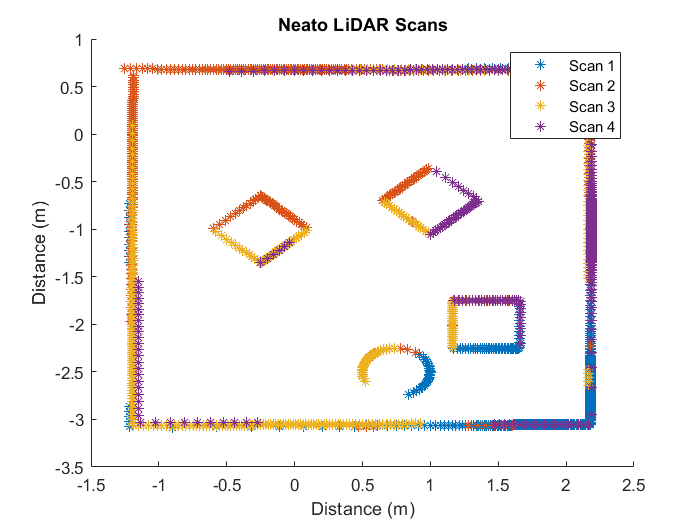

final_lidar_to_global

### Contour Plot Generation

Now that we have the scanned data, we can generate a contour. The following contour was generated with the known locations and sizes of the walls, obstacles, and BoB. Additionally, we used Matlab's symbolic toolbox to keep track of the explicit function that represents the contour plot.

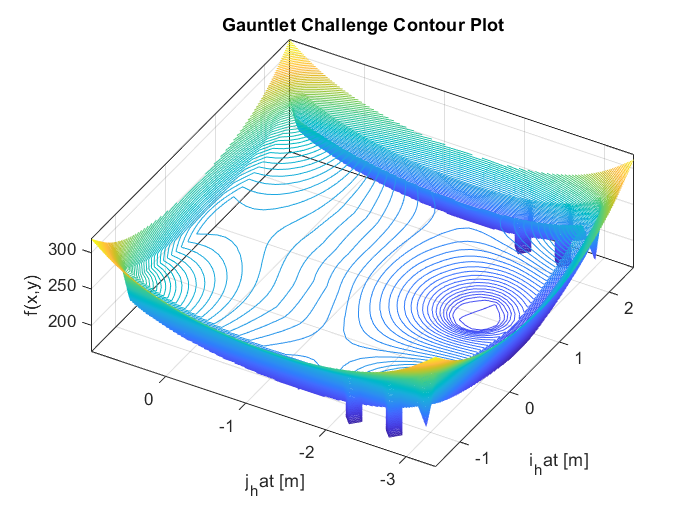

final_contour_plot

### Path of Gradient Descent

Text

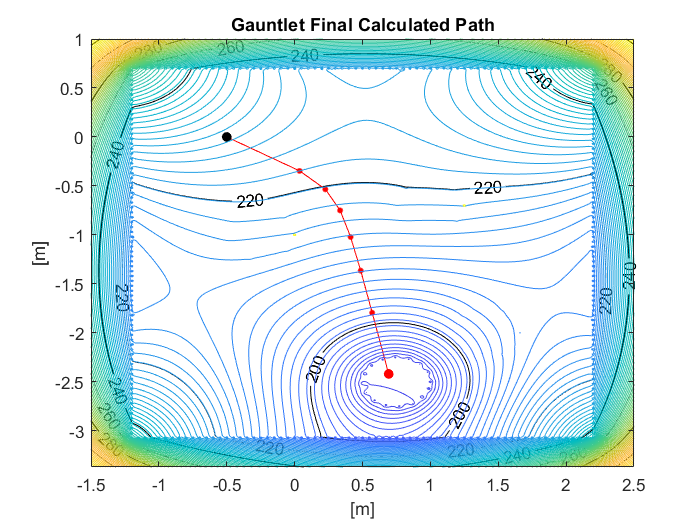

final_neato_planned_path

### Experimental Validation

Actually running the program to traverse the playpen took the Neato approximately 10 seconds when applying an angular speed of 0.2 radians per second and linear speed of 0.5 meters per second. Below is a detailed plot of how the Neato was *supposed* to travel (in red) and how the Neato actually navigated the gradient descent (dashed) towards the Bucket of Benevolence.

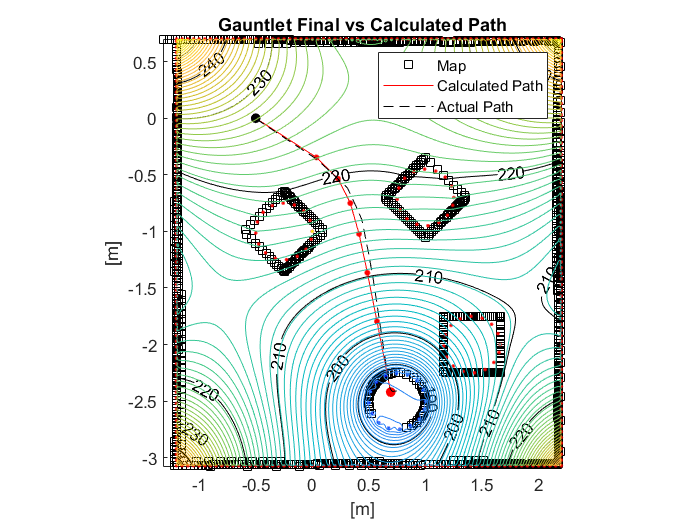

final_neato_path

### Video

Here is a video of our robot in action:

[https://www.youtube.com/watch?v=ZeCVrFRTlag](https://www.youtube.com/watch?v=ZeCVrFRTlag)

### Code

Here is a link to our code:

[https://github.com/ArturoJoya/GauntletZ13](https://github.com/ArturoJoya/GauntletZ13)